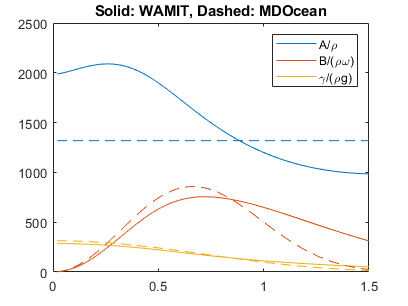

%hydro = struct();
%hydro = readWAMIT(hydro,'rm3.out',[]); % function from WECSim
w = hydro.w;
A = hydro.A(3,3,:);
A = A(:);
B = hydro.B(3,3,:);
B = B(:);
gamma = hydro.ex_ma(3,1,:);
gamma = gamma(:);

r = 10;
fudge_factor =  5;
draft = 2;
g = 9.8;
rho_w = 1000;

k = w.^2 / g;
V_g = g ./(2*w);

A_MDOcean = 1/2 * 4/3 * pi * r^3 * 0.63;
r_k_term = r^2 - 1/8 * k.^2 * r^4 + 1/192 * k.^4 * r^6 - 1/9216 * k.^6 * r^8;
gamma_MDOcean   = pi * exp(-k * draft * fudge_factor) .* r_k_term; 
B_MDOcean = k/2 .* gamma_MDOcean.^2;

figure
plot(w,A,w,B,w,gamma)
hold on
set(gca,"ColorOrderIndex",1)
plot(w,ones(size(w))*A_MDOcean,'--',w,B_MDOcean,'--',w,gamma_MDOcean,'--' )
xlim([0 1.5])
ylim([0 2500])
legend('A/\rho','B/(\rho\omega)','\gamma/(\rhog)')
title('Solid: WAMIT, Dashed: MDOcean')

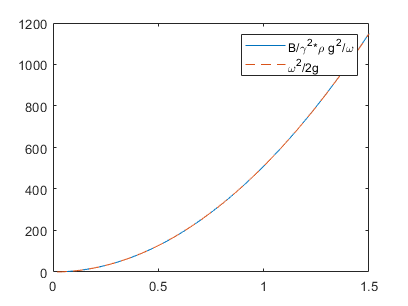


figure
plot(w,B./gamma.^2*10000, w,w.^2/(2*9.8)*10000,'--')
legend('B/\gamma^2*\rho g^2/\omega', '\omega^2/2g')
xlim([0 1.5])